disp('linear regression for exponential model ');

linear regression for exponential model 


%exponential model 
% y=𝑏𝑒^ax
x = [0.2 0.4 0.8 1.2 1.6 2.4] ; 
y = [550 750 1000 1400 2000 3750];

% ln y= ax + ln b 
% Y = ax + B
%take the log for the y vector
Y = log(y) ;

% ∑ Y = a ∑ x + n B
% ∑ Yx = a ∑ x^2 + B ∑ x

% get variable values

n=length(x)     ; % n  
sx = sum(x)     ; % ∑ x
sY = sum(Y)     ; % ∑ Y
sxY = sum(x.*Y) ; % ∑ Yx
sx2 = sum(x.^2) ; % ∑ x^2

% ∑ Y = a ∑ x + n B
% ∑ Yx = a ∑ x^2 + B ∑ x

% we split this two equation into two matrices

Rightcoef = [sx n  ; sx2 sx ] ;  
Leftcoef = [sY ; sxY] ; 
%solve as matrices
%think of it as 
%Leftcoef = Rightcoef  * sol
sol = Rightcoef \ Leftcoef  ; % as same as 'sol  = Rightcoef^-1 * Leftcoef' but the backslash expression is more effcint for more info : https://www.mathworks.com/help/matlab/ref/mldivide.html

a = sol(1) ; %a
B = sol(2) ; %B
b = exp(sol(2)) ; %b 

%calc R^2
yav = mean(Y) ;
st = sum( (Y-yav).^2 )  ;
sr = sum((Y-B-a*x).^2) ;
r2=(st-sr)/st ;


disp('a ');disp(a) ;

a 
    0.8497



disp('b ');disp(b) ;

b 
  501.4058



disp('r^2 ');disp(r2) ;

r^2 
    0.9953



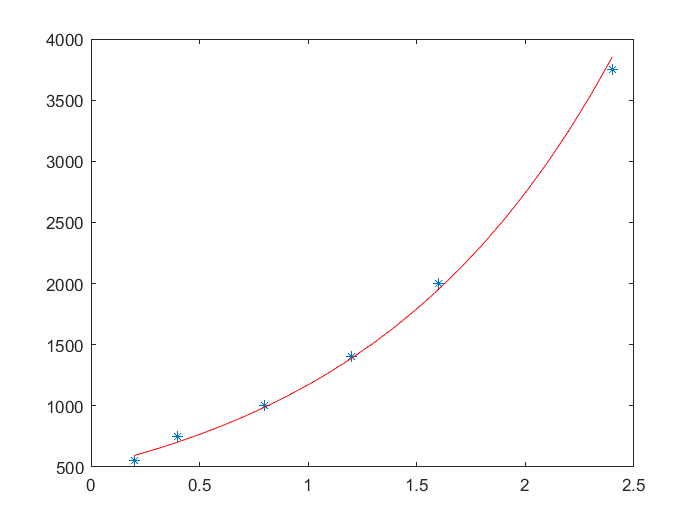


x1 = min(x):0.1:max(x) ;
%y=b*e^ax
y1 = b*exp(a*x1);

plot(x,y ,'*' , x1 ,y1 ,'r-')